## EnGP User Guide

This live script will talk you through how to run a basic model using the EnGP Matlab framework. The framework is built using OOP principles and we approach the problem by creating a GP object which contains all the data required for analysis. Although some components can be called independently, it is recommended that the code is accessed through the GP object.

Let;s start by creating some toy data to show how a GP model can be used to predict.

x = (-5:0.1:5)'; % Define some data


Define hyperparameters to generate model from

hyps.sf2 = 5;
hyps.ll = 5;
hyps.sn2 = 0.01;


Create a kernel object to generate the covariance matrix

kern = Kernel('Matern32',hyps);
K = kern.Matern32(x,x);


y is a draw from the GP

y = mvnrnd(zeros(length(x),1),K)';


Plot the target function that we have drawn from the GP

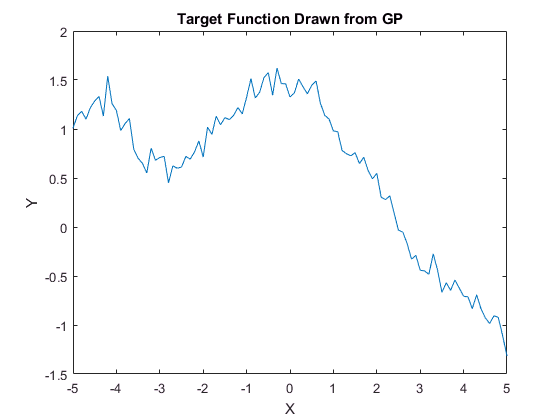

figure
plot(x,y)
xlabel('X')
ylabel('Y')
title('Target Function Drawn from GP')

To begin using the EnGP package you first need a Gaussian process object, by convention we call this gp, if more specific naming is needed this can be appended to the name, e.g. gp_batch1

gp = EnGP();


The first thing we need to do is assign data to the gp object this is done with the set data method

gp.set_data(x,y);

ans =   Train with properties:

          name: 'Training Data'
        inputs: [101x1 double]
        target: [101x1 double]
    normalised: 1


Data can be added to one of three groups, training, validation, or test. The command above adds the data by default to the training group if none is specified. We will add a copy of the data to the test group.

gp.set_data(x,y,'test');

ans =   Test with properties:

          name: 'Test Data'
        inputs: [101x1 double]
        target: [101x1 double]
    normalised: 1


The next step in setting up the EnGP model is defining the model structure, there are currently two options for this Static models or NARX models. We will assign a static model.

gp.set_model(@Static);

If assigning a NARX model this command takes 4 additional arguments, these being: the number of lags on x, the number of lags on y, and the lag multipliers on x and y. Lastly tp finish setting up the model we will need to specify which underlying GP formulation will be used. As part of this we also specify a kernel.

gp.set_process(@GPR,Kernel('Matern32',hyps));

The command above sets the process to be full GP regression using a Matern 3/2 Kernel with the hyperparameters we specified earlier. We can also set some of the properties of the model which control how the model behaves. Notably we can change the optimiser from the default conjugate gradient to a population based optimiser.

gp.props.optimiser = 'QPSO';

All that is left to do is optimise the hyperparameters of the model.

gp.optimise();

Best min = -2.8068687716e+01
Best min = -2.8068687716e+01
Best min = -3.4790683680e+01
Best min = -3.4951837718e+01
Best min = -3.9011013281e+01
Best min = -3.9220682997e+01
Best min = -3.9220682997e+01
Best min = -3.9436867166e+01
Best min = -4.0023768118e+01
Best min = -4.0393340883e+01
Best min = -4.0474827469e+01
Best min = -4.0483258648e+01
Best min = -4.0520763785e+01


ans = Function Tolerance Reached in 13 generations!
 Average Change = 6.904e-03


Now the optimised hyperparameters are stored in the model, we can predict back on the training data.

gp.predict('train')

Model error: 1.02659131


ans =   EnGP with properties:

                    props: [1x1 Properties]
                       xp: [101x1 double]
               predict_on: 'train'
                     data: [1x1 Data]
                    model: [1x1 Static]
                  process: [1x1 GPR]
    prediction_normalised: 0
                     hyps: [1x1 struct]


The predicitons are stored in the GP object. If we want to retrieve the means and variances we can access them directly

gp.process.mp

ans =     1.0505
    1.0980
    1.1434
    1.1862
    1.2271
    1.2620
    1.2854
    1.2932
    1.2824
    1.2441


gp.process.vp

ans =     0.0130
    0.0112
    0.0107
    0.0105
    0.0105
    0.0105
    0.0105
    0.0105
    0.0105
    0.0105


We can also plot the predictions, for a high dimensional model or NARX model we can set the process to only plot the outputs against each other with the command gp.props.plot_type = 'output';

However, in this demo we will plot the inputs against the outputs.

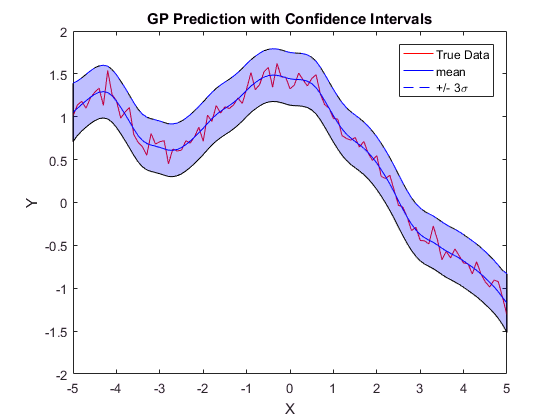

figure
gp.plot();

We can also retrieve the normalised mean square error of the process with the command:

gp.process.nmse

ans = 1.0266

 If you have any questions, or for advanced usage notes please email trogers3@sheffield.ac.uk